# Create Library

This example shows how to use the **Generate JavaScript using MATLAB Coder** add-on to create a JavaScript® "Hello Browser!" library. You can then run the JavaScript code sample in a browser to show a "Hello Browser!" on the browser console line.

## Set Up the Project

1. In the MATLAB® current folder browser, navigate to a folder where you can create and store your library project and files.

2. Create the library project by entering this code in MATLAB command line. Specify a name and the directory for your library.The `dll` argument creates the project with a library configuration.

proj = webcoder.setup.project("My Library","Directory",pwd,"OutputType",'dll');

3. Create a MATLAB function that calls the `webcoder.console.log` function to print `'Hello Browser!'` to the browser console.

4. Add the `HelloBrowser.m` function file to the project.

5. Add the **UserEntryPoints > Function** label to the `HelloBrowser.m` function file. This image shows an example of a project and the label.

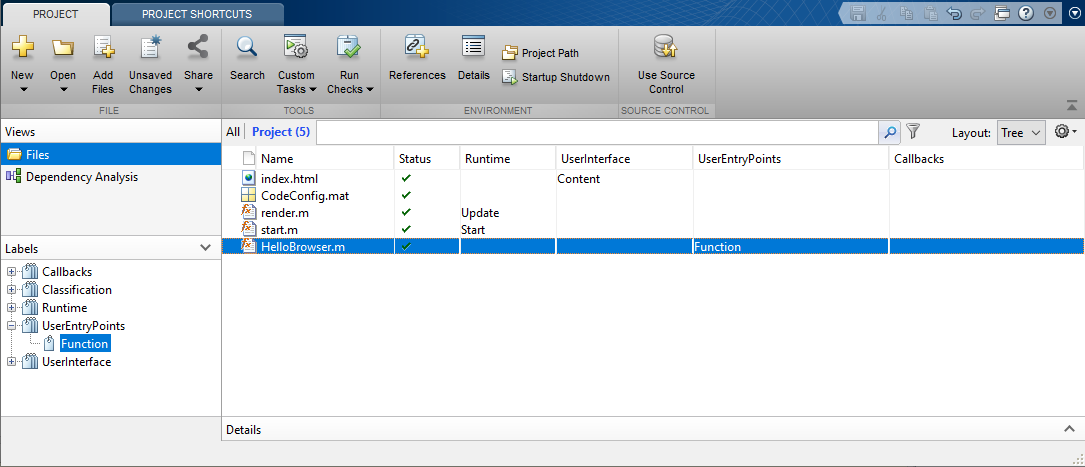

## Generate the JavaScript and WebAssembly Code

At the MATLAB command prompt, enter this code to build the project and MATLAB code.

proj = openProject(pwd);
webcoder.build.project(proj);

This generates C/C++ code into the build folder. The C/C++ code then compiles to a JavaScript file, `mylibrary.js`, and a WebAssembly file, `mylibrary.wasm`, in the `dist` folder. 

You can add this code as a sample `index.html `file for a web page to the `dist` folder. It includes code to run the generated code `mylibrary.js` file in the browser.

## Run the JavaScript and WebAssembly Code

From the MATLAB command line, you can launch the sample web page in a local server. To create the server and launch the app in the `dist folder`, enter this code. Run the commands in the same folder as the provided `index.html` file.

server = webcoder.utilities.DevelopmentServer("Port",8125)
start(server);

Stop the server at any time using this command.

stop(server);

Open the web page using any modern browser at this IP address: [127.0.0.1:8125](http://127.0.0.1:8125). While in the browser, press **Ctrl+Shift+I** to open the development view. The output from the `mylibrary.js` file will displays in the Console tab.